% 支持向量机svm
svmParams = templateSVM('KernelFunction', 'gaussian', ...
    'BoxConstraint', 1, 'KernelScale', 'auto');
Mdl = fitcecoc(train_X, train_y, 'Learners', svmParams);

preds = predict(Mdl, test_X);
preds_train = predict(Mdl, train_X);
accuracy = sum(preds == test_y) / numel(test_y)

accuracy = 1

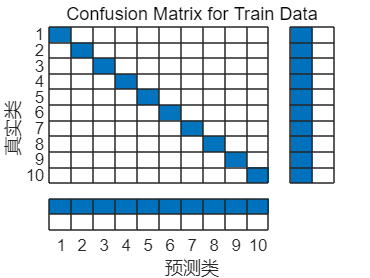

% 混淆矩阵
figure
cm = confusionchart(preds_train, train_y);
cm.Title = 'Confusion Matrix for Train Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

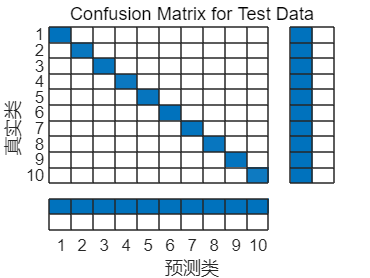

    
figure
cm = confusionchart(preds, test_y);
cm.Title = 'Confusion Matrix for Test Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';